### Exercise 4

Solve Equation with K and r

syms t N(t) K r x
assume(K,"positive");assume(r,"positive");
dN = diff(N,t);
EQN = dN - r*N*(1-N/K); % symbolic function
Nsolg = dsolve(EQN)

$$Nsolg = \left(\begin{array}{c} \frac{K}{{\mathrm{e}}^{C_{1}-r\,t}+1}\\ 0\\ K \end{array}\right)$$

fN = r*N*(1-N/K) % symbolic flow

$$fN(t) = -r\,N\left(t\right)\,\left(\frac{N\left(t\right)}{K}-1\right)$$

Fixed Points:

% Use the independent variable x instead of N(t)
r = 1; K = 1; % Fix r and K to 1
fx = r*x*(1-x/K)% write the flow in terms of x

$$fx = -x\,\left(x-1\right)$$

% Symbolically: It is exact but only sometimes works
Fpts1 = solve(fx)% Use solve(?) for obtaining the Fixed points

$$Fpts1 = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

% Numerically: Always works but it is not exact: double precision
Fpts2 = double(vpasolve(fx)) % use double(vpasolve(??)) for solving it numerically

Fpts2 =      0
     1


Stability:

% Derivative:
fxd = diff(fx) % Get Derivative of fx respect to x

$$fxd = 1-2\,x$$

fxd_Fpts = subs(fxd,x,Fpts1) % Calculate derivative at Fixed Points

$$fxd\_Fpts = \left(\begin{array}{c} 1\\ -1 \end{array}\right)$$

disp('Stable Fixed Points:'); Fpts1(fxd_Fpts<0)   % Those Fixed Points with neg der

Stable Fixed Points:


$$ans = 1$$

disp('Unstable Fixed Points:'); Fpts1(fxd_Fpts>0) % Those Fixed Points with pos der

Unstable Fixed Points:


$$ans = 0$$

% Exploring Neighbourhood
epsilon = 1e-3;
neigB = [Fpts1-epsilon, Fpts1+epsilon] % Move Epsilon around the Fixed Points

$$neigB = \left(\begin{array}{cc} -\frac{1}{1000} & \frac{1}{1000}\\ \frac{999}{1000} & \frac{1001}{1000} \end{array}\right)$$

fx_M = double(subs(fx,x,neigB))   % compute flow around fixed points

fx_M =    -0.0010    0.0010
    0.0010   -0.0010


vec_neigB = diff(fx_M,1,2) % Estimate the slope

vec_neigB =     0.0020
   -0.0020


disp('Stable Fixed Points:'); stb = Fpts1(vec_neigB<0)% Those Fixed Points with neg slope

Stable Fixed Points:


$$stb = 1$$

disp('Unstable Fixed Points:'); nstb = Fpts1(vec_neigB>0)% Those Fixed Points with neg eslope

Unstable Fixed Points:


$$nstb = 0$$

Phase Portrait

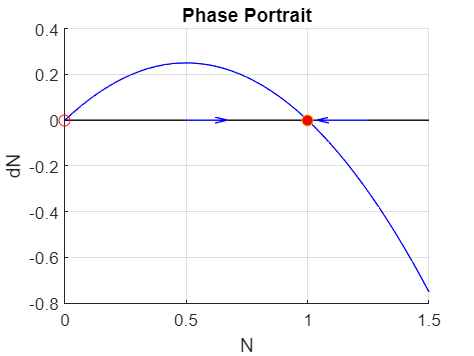

figure; hold on;
plot([0,1.5],zeros(1,2),'k');
fplot(fx,[0,1.5],'b');
plot(stb,zeros(size(stb)),'o','MarkerFaceColor','r')
plot(nstb,zeros(size(nstb)),'ro')
quiver([0.5,1.25],zeros(1,2),subs(fx,x,[0.5,1.25]),zeros(1,2),0.4,'b')
xlabel('N'); ylabel('dN'); grid on; title('Phase Portrait');

Trayectories using Numeric Runge-Kutta ODE45 method

t0 = 0; tf = 10; % init anf final time 0 10
K = 1; r = 1;
fN_lmb = @(t,y) r*y.*(1-y/K); % lambda function of the fx
y0 = 0:0.2:2; tspan = [t0,tf]; % y0 Vector from 0 to 2 steps 0.2
[ts,ys] = ode45(fN_lmb,tspan,y0)

ts =          0
    0.0502
    0.1005
    0.1507
    0.2010
    0.2984
    0.3959
    0.4934
    0.5909
    0.7182


ys =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000
         0    0.2082    0.4121    0.6120    0.8079    1.0000    1.1884    1.3731    1.5543    1.7321    1.9066
         0    0.2166    0.4243    0.6239    0.8156    1.0000    1.1775    1.3484    1.5132    1.6721    1.8255
         0    0.2252    0.4367    0.6356    0.8230    1.0000    1.1673    1.3258    1.4761    1.6188    1.7546
         0    0.2341    0.4490    0.6471    0.8302    1.0000    1.1578    1.3050    1.4424    1.5712    1.6920
         0    0.2520    0.4733    0.6691    0.8435    1.0000    1.1411    1.2690    1.3855    1.4919    1.5896
         0    0.2708    0.4976    0.6903    0.8560    1.0000    1.1263    1.2381    1.3376    1.4267    1.5071
         0    0.2905    0.5220    0.7107    0.8676    1.0000    1.1133    1.2113    1.2970    1.3725    1.4397
         0    0.3110    0.5462    0.7304    0.8784    1.0000    1.1017    1.1880    1.2622    1.3267    1.3

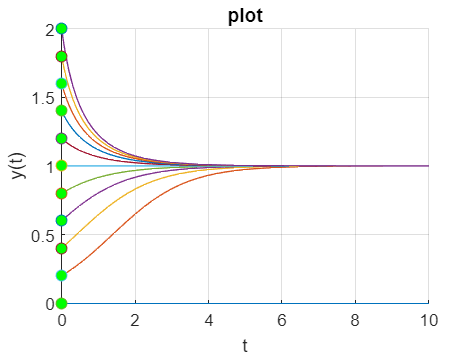


figure;hold on;
plot(ts,ys);plot(0,y0,'o','MarkerFaceColor','g');
axis([t0,tf,0,2])
xlabel('t');ylabel('y(t)');grid on; title('plot');